# Лекция 1 Квантовое описание свободного движения

## 1.1. Волна де Бройля

Условие нормировки волновой функции


$$\int |\Psi \left(\mathit{\mathbf{r}},t\right)|^2 d^3 r=1$$


Гипотеза де Бройля в том, что свободной частице соответствует волновая функция (волна де Бройля)


$$\Psi \left(r,t\right)=\Psi_0 e^{i\frac{\;\mathit{\mathbf{p}}\;\mathit{\mathbf{r}}-E\;t}{\hbar }}$$


clear
syms Psi(r,t) Psi0 p r E t hp
Psi(r,t)==Psi0*exp(i*(p*r-E*t)/hp)

$$ans = \Psi \left(r,t\right)=\Psi_{0}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,r\,\mathrm{i}}{\mathrm{hp}}}$$

Но при таком описании возникают две трудности

1) Интерграл


$$\int |\Psi \left(\mathit{\mathbf{r}},t\right)|^2 d^3 r=|\Psi_0 |^2 \int d^3 r$$


не сходится.

2) Пусть v - классическая скорость частицы. Тогда фазовая скорость волны де Бройля 


$$v_{\mathrm{ph}} =\frac{\omega }{k}=\frac{E}{p}$$


не совапдает с v.

Действительно, в нерелятивистском случае

syms E p m v_ph v
E==p^2/(2*m) , ...  % =>
    v_ph==p/(2*m)==v/2

$$ans = \text{E}=\frac{p^{2}}{2\,m}$$

$$ans = \left(v_{\mathrm{ph}}=\frac{p}{2\,m}\right)=\frac{v}{2}$$

тогда как в релятивистском случае

syms E p c m v_ph
E==sqrt(p^2*c^2+m^2*c^4) , ... % =>
    v_ph==E/p==sqrt(c^2+m^2*c^4/p^2)>c

$$ans = \text{E}=\sqrt{c^{4}\,m^{2}+c^{2}\,p^{2}}$$

$$ans = c<\left(\left(v_{\mathrm{ph}}=\frac{\text{E}}{p}\right)=\sqrt{c^{2}+\frac{c^{4}\,m^{2}}{p^{2}}}\right)$$

Поэтому, не отказываять от волны де Бройля, наметим иной подход к описанию свободной частицы.

## 1.2. Суперпозиция волн де Бройля

clear
syms x p r E t hp real
assume(hp>0)
syms Psi0
Psi(x,t)=Psi0*exp(i*(p*x-E*t)/hp)

$$Psi(x, t) = \Psi_{0}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,x\,\mathrm{i}}{\mathrm{hp}}}$$

Складывая (интегрирую) волны де Бройля в с весами C(p) получим волновую функцию

syms C(p)
Psi(x,t)=int(C(p)*Psi0*exp(i*(p*x-E*t)/hp),p,-inf,inf)

$$Psi(x, t) = \int_{-\infty }^{\infty }\Psi_{0}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,x\,\mathrm{i}}{\mathrm{hp}}}\,C\left(p\right)\mathrm{d}p$$

Такую волновую функцию называют волновым пакетом.

Исследуем интеграл от квадрата модуля волнового пакета.

I=simplify(int(Psi'*Psi,x,-inf,inf))

$$I(t) = \int_{-\infty }^{\infty }{\left|\Psi_{0}\,\int_{-\infty }^{\infty }{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,x\,\mathrm{i}}{\mathrm{hp}}}\,C\left(p\right)\mathrm{d}p\right|}^{2}\mathrm{d}x$$

I=2*pi*hp*abs(Psi0)^2*int(abs(C(p))^2,p,-inf,+inf)

$$I = 2\,\pi \,\mathrm{hp}\,{\left|\Psi_{0}\right|}^{2}\,\int_{-\infty }^{\infty }{\left|C\left(p\right)\right|}^{2}\mathrm{d}p$$

Пусть

Psi0==1/sqrt(2*pi*hp)

$$ans = \Psi_{0}=\frac{\sqrt{2}}{2\,\sqrt{\mathrm{hp}}\,\sqrt{\pi }}$$

тогда условие нормировки выглядит так

syms Psi(x,t)
int(abs(Psi(x,t))^2,x,-inf,inf)==int(abs(C(p))^2,p,-inf,+inf)==1

$$ans = \left(\int_{-\infty }^{\infty }{\left|\Psi \left(x,t\right)\right|}^{2}\mathrm{d}x=\int_{-\infty }^{\infty }{\left|C\left(p\right)\right|}^{2}\mathrm{d}p\right)=1$$

Итак, пусть волна де Бройля - это

syms Psi_p(x,t)
Psi_p(x,t)==1/sqrt(2*pi*hp)*exp(i*(p*x-E*t)/hp)

$$ans = \Psi_{p}\left(x,t\right)=\frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,x\,\mathrm{i}}{\mathrm{hp}}}}{2\,\sqrt{\mathrm{hp}}\,\sqrt{\pi }}$$

Тогда волновой пакет имеет вид

Psi(x,t)==int(C(p)*Psi_p(x,t),p,-inf,inf)

$$ans = \Psi \left(x,t\right)=\int_{-\infty }^{\infty }C\left(p\right)\,\Psi_{p}\left(x,t\right)\mathrm{d}p$$

## 1.3. Модельный волновой пакет

clear
syms C0 x t p p0 dp hp
assume(dp>0)
C(p)=piecewise(p0-dp<=p<=p0+dp,C0,0)

$$C(p) = \left\{ \begin{array}{cl} C_{0} & \text{ if }p\leq \mathrm{dp}+p_{0}\wedge p_{0}\leq \mathrm{dp}+p\\ 0 & \mathrm{otherwise} \end{array}\right.$$

И пусть $\Delta p<<p_0$ , тогда в окрестности $p_0$

syms E0 dEp0
E(p)=E0+(p-p0)*dEp0

$$E(p) = E_{0}+{\mathrm{dEp}}_{0}\,\left(p-p_{0}\right)$$

Запишем $\Psi$-функцию, отвечающую такой $C\left(p\right)$

syms C0 p0 dp hp p x E t
Psi(x,t)=C0*int(1/sqrt(2*pi*hp)*exp(i*(p*x-E*t)/hp),p,p0-dp,p0+dp)

$$Psi(x, t) = -\frac{\sqrt{2}\,C_{0}\,\sqrt{\mathrm{hp}}\,\left({\mathrm{e}}^{\frac{\left(x\,\left(\mathrm{dp}+p_{0}\right)-\text{E}\,t\right)\,\mathrm{i}}{\mathrm{hp}}}-{\mathrm{e}}^{-\frac{\left(\text{E}\,t+x\,\left(\mathrm{dp}-p_{0}\right)\right)\,\mathrm{i}}{\mathrm{hp}}}\right)\,\mathrm{i}}{2\,x\,\sqrt{\pi }}$$

После упрощения получаем

syms f(x)
Psi(x,t)=(C0*hp/sqrt(2*pi*hp))*exp(i*(p0*x-E0*t)/hp)*f(x-dEp0*t)

$$Psi(x, t) = \frac{\sqrt{2}\,C_{0}\,\sqrt{\mathrm{hp}}\,{\mathrm{e}}^{-\frac{E_{0}\,t\,\mathrm{i}-p_{0}\,x\,\mathrm{i}}{\mathrm{hp}}}\,f\left(x-{\mathrm{dEp}}_{0}\,t\right)}{2\,\sqrt{\pi }}$$

% where
syms xi x1
f(x1)=simplify(int(exp(i*xi*x1),xi,-dp/hp,dp/hp))

$$f(x1) = \frac{2\,\sin\left(\frac{\mathrm{dp}\,x_{1}}{\mathrm{hp}}\right)}{x_{1}}$$

График функции $f\left(\tilde{x} \right)$ представлен на рисунке.

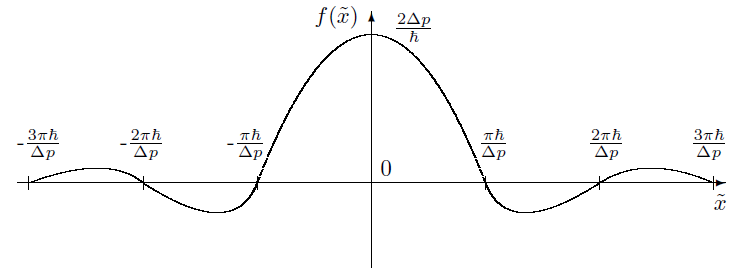

Найдем отношение  двух первых максимумов $|f\left(x\right)|$

assume(hp>0)
assume(dp>0)
digits(3)
f1=abs(f(3/2*pi*hp/dp))

$$f1 = \frac{4\,\mathrm{dp}}{3\,\mathrm{hp}\,\pi }$$

f0=limit(f(x),x,0)

$$f0 = \frac{2\,\mathrm{dp}}{\mathrm{hp}}$$

pp=vpa(simplify(f1/f0))

$$pp = 0.212$$